# Case 1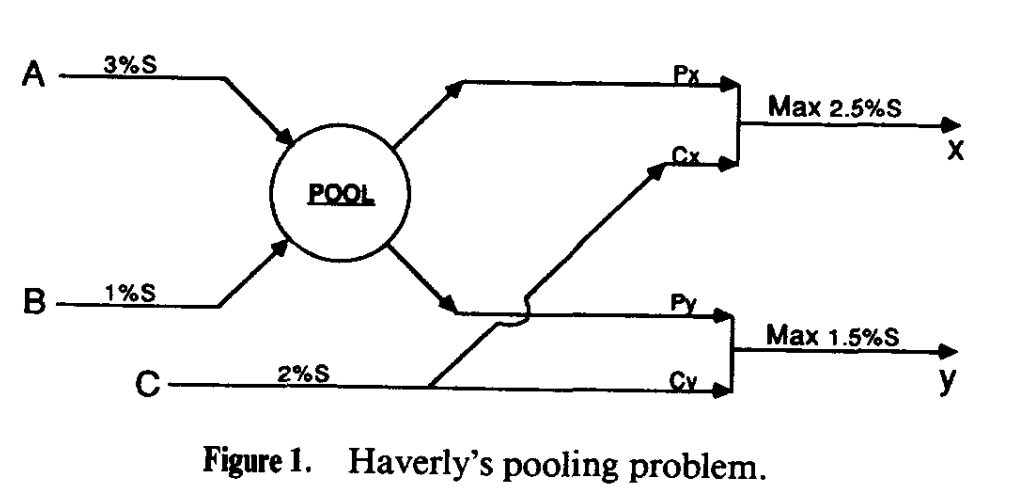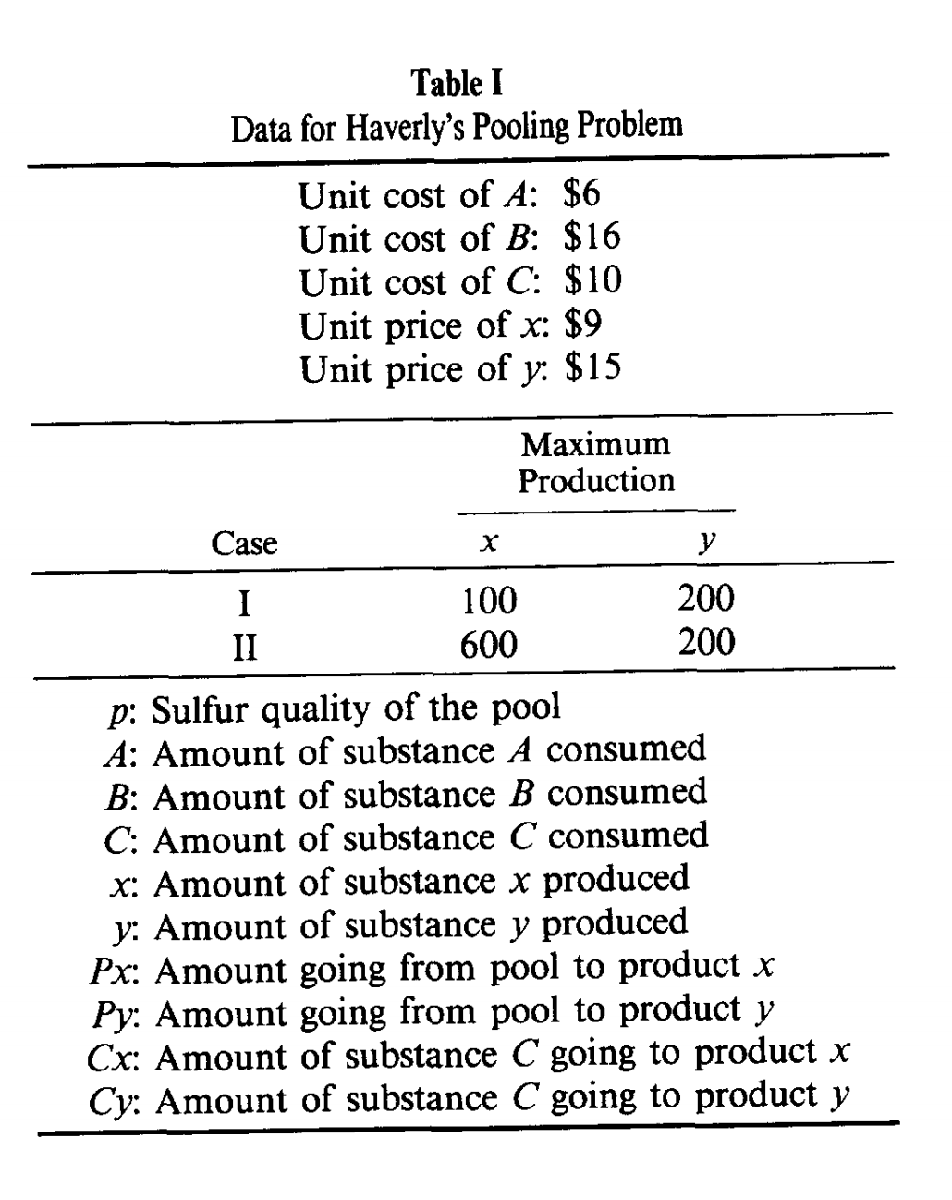

## 变量声明

A=sdpvar(1,1);
B=sdpvar(1,1);
C=sdpvar(1,1);
Px=sdpvar(1,1);
Py=sdpvar(1,1);
Cx=sdpvar(1,1);
Cy=sdpvar(1,1);
X=sdpvar(1,1);
Y=sdpvar(1,1);
X_u=100;
Y_u=200;
p=sdpvar(1,1);%汇流性质猜值
f=sdpvar(1,1);%分流比率
Rprop=sdpvar(1,1);%性质误差

## 目标函数

Cost=6*A+16*B+10*(Cx+Cy)-9*X-15*Y-999*(Rprop^2);%min

## 猜值设定

% p=1.5;
% f=0.5;

## 约束条件

Const=[];
Const=Const+(Px+Py-A-B==0);
Const=Const+(X-Px-Cx==0);
Const=Const+(Y-Py-Cy==0);
Const=Const+(p*Px+2*Cx-2.5*X+f*Rprop<=0);
Const=Const+(p*Py+2*Cy-1.5*Y+(1-f)*Rprop<=0);
Const=Const+(p*Px+p*Py-3*A-B+Rprop==0);
Const=Const+([A,B,C,Px,Py,Cx,Cy,X,Y,f]>=0);
Const=Const+(X<=X_u);
Const=Const+(Y<=Y_u);
Const=Const+(f<=1);

## 求解

ops=sdpsettings('solver','ipopt');

sol=optimize(Const,-Cost,ops)

sol = 包含以下字段的 struct :
    solvertime: 0
          info: 'Solver not found (ipopt)'
       problem: -3
    yalmiptime: 0.7190


## 结果打印

value([A,B,C,Px,Py,Cx,Cy,X,Y,f,p,Cost,Rprop])

ans =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
